# Controllo della temperatura di una casa

## Descrizione del problema

L'obiettivo del progetto è regolare la temperatura di una casa utilizzando un controllore MPC. Si ipotizza che la casa non condivida alcun muro esterno con altre abitazioni, che i ﬂussi d'aria tra le stanze della casa siano trascurabili e che il riscaldamento della casa sia affidato a tre termosifoni, uno per ogni stanza. La pianta della casa in oggetto è mostrata nella figura seguente:

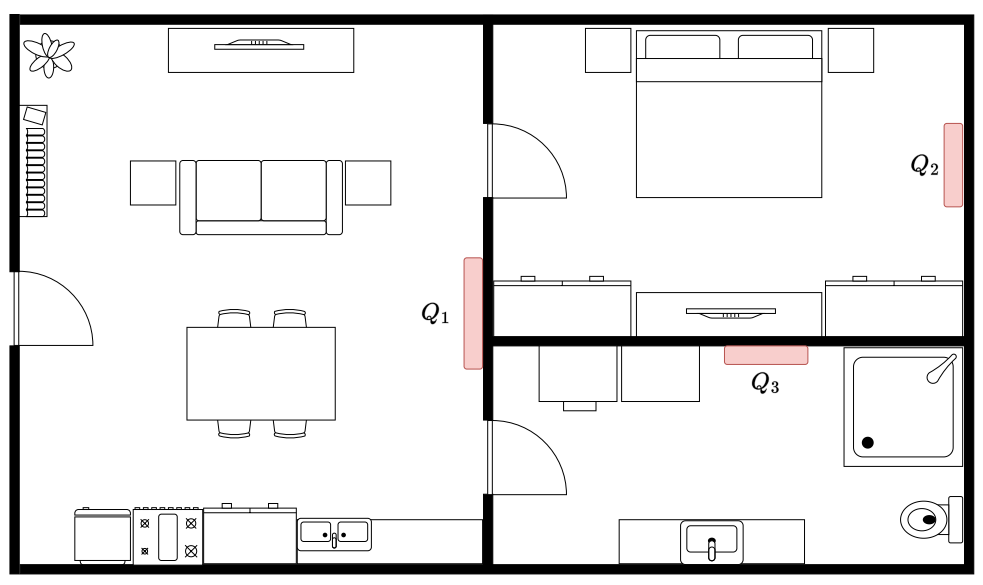

Figura 1: Planimetria della casa.

La dinamica della temperatura all’interno della casa è deﬁnita dalle equazioni seguenti:

$\begin{cases}
C_1\dot{T}_1(t) = Q_1(t) - k_{1,2}(t)(T_1(t)-T_2(t)) - k_{1,3}(t)(T_1(t)-T_3(t)) - k_{ext}(T_1(t)-T_{ext})\\
C_2\dot{T}_2(t) = Q_2(t) + k_{1,2}(t)(T_1(t)-T_2(t)) - k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_2(t)-T_{ext})\\
C_3\dot{T}_3(t) = Q_3(t) + k_{1,3}(t)(T_1(t)-T_3(t)) + k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_3(t)-T_{ext})\\
\dot{Q}_1 = (Q_{1,r}(t)-Q_1(t))/\tau_1 \\
\dot{Q}_2 = (Q_{2,r}(t)-Q_2(t))/\tau_2\\
\dot{Q}_3 = (Q_{3,r}(t)-Q_3(t))/\tau_3
\end{cases}$  con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|T_i \left(t\right)-T_j \left(t\right)\right\|}_2 } }$

Il significato delle grandezze presenti nelle precedenti equazioni è il seguente:

- $T_i\;[K]$ è la temperatura della i-esima stanza;

- $T_{ext}\;[K]$ è la temperatura esterna, ipotizzata costante.

- $C_i\;[J/s]$ è la capacità termica della i-esima stanza;

- $k_{i,j}\;[W/K]$ è un parametro che regola lo scambio di calore tra l’i-esima e la j-esima stanza;

- $k_{ext}\;[W/K]$ è un parametro che regola lo scambio di calore tra le stanze della casa e l’esterno;

- $Q_i\;[W]$ è la potenza termica dell’i-esimo termosifone;

- $Q_{i,r}\;[W]$ è la potenza termica di riferimento dell’i-esimo termosifone;

- $\tau_i\;[s]$ è la costante di tempo dell’i-esimo termosifone. 

I parametri noti sono riportati nella tabella seguente:


$$\matrix{
\textbf{Parametro} & \textbf{Valore} & \textbf{Unità}    \cr
C_1 		& 6800 		& J/s	        \cr
C_2			& 5600		& J/s		\cr
C_3	        	& 5100 		& J/s		\cr
\bar{k}_{1,2} 		& 15 		& W/K	        \cr
\bar{k}_{1,3}		& 20	         	& W/K		\cr
\bar{k}_{2,3}	       	& 15 		& W/K		\cr
k_{ext}	       	& 8 	        	& W/K		\cr
T_{ext}	       	& 278        	& K    		\cr
\tau_1 		& 400 		& s	                \cr
\tau_2		& 450		& s		        \cr
\tau_3        	& 450 		& s	        	\cr
}$$


Tabella 1: Parametri noti del sistema in esame.

La potenza erogata dai tre termosifoni è non-negativa e mai superiore ai 150W, mentre la temperatura all’interno delle tre stanze non deve mai scendere al di sotto dei 286K.

Gli ingressi controllati del sistema sono le potenze di riferimento dei tre termosifoni, $Q_{i,r}$, $i \in \{1,2,3\}$.

L’obiettivo del lavoro è progettare un controllore MPC in grado di portare il sistema dalla condizione iniziale $(T_1, T_2 , T_3 , Q_1 , Q_2 , Q_3 ) = (288, 288, 288, 0, 0, 0)$ all’equilibrio $(293, 293, 293, 120, 120, 120)$, rispettando sempre i vincoli, e simulare il funzionamento del sistema in anello chiuso. Il tempo minimo di campionamento, $T_s$, è pari ad $1\;s$.

## Parametri costanti del modello della casa

Inizialmente, si creano delle variabili per salvare tutti i parametri noti del modello.

clc
close all
clear
T_ext = 278; % [K], temperatura esterna ipotizzata costante
C_termica = [6800 5600 5100]; % [J/s], capacità termica della i-esima stanza
k_bar = [15 20 15]; % [W/K], scambio di calore fra l'i-esima e la j-esima stanza 
k_ext = 8; % [W/K], scambio di calore fra le stanze e l'esterno
Q_ref = [150 150 150]; % [W], potenza termica di riferimento dell'i-esimo termosifone
tau = [400 450 450]; % [s], costante di tempo dell'i-esimo termosifone
x_eq = [293 293 293 120 120 120]';
x_ci = [288 288 288 0 0 0]';
% x_ci = [294 294 294 100 100 100]'; % c.i. alternativa per uguaglianza

## Equazioni del sistema in variabili di stato

Prima di procedere ad analizzare il sistema, è necessario riscrivere le equazioni della sua dinamica nello spazio degli stati. Si definiscono il vettore degli stati, $\mathbf{x}$, ed il vettore degli ingressi, $\mathbf{u}$:

$\mathbf{x} = [x_1, x_2, x_3, x_4, x_5, x_6 ]'
:= [T_1, T_2, T_3, Q_1, Q_2, Q_3]'$, $\mathbf{x}\in \mathbb{R}^6$

$\mathbf{u} = [u_1, u_2, u_3]' := [Q_{1,r},\;Q_{2,r},\;Q_{3,r}]'$, $\mathbf{u}\in \mathbb{R}^3$

Il sistema diventa quindi:

$\begin{cases}
\dot{x}_1(t) = (x_4(t) - k_{1,2}(t)(x_1(t)-x_2(t)) - k_{1,3}(t)(x_1(t)-x_3(t)) - k_{ext}(x_1(t)-T_{ext}))/C_1\\
\dot{x}_2(t) = (x_5(t) + k_{1,2}(t)(x_1(t)-x_2(t)) - k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_2(t)-T_{ext})/C_2\\
\dot{x}_3(t) = (x_6(t) + k_{1,3}(t)(x_1(t)-x_3(t)) + k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_3(t)-T_{ext})/C_3\\
\dot{x}_4 = (u_1(t)-x_4(t))/\tau_1 \\
\dot{x}_5 = (u_2(t)-x_5(t))/\tau_2\\
\dot{x}_6 = (u_3(t)-x_6(t))/\tau_3
\end{cases}$ con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|x_i \left(t\right)-x_j \left(t\right)\right\|}_2 } }$

Le equazioni vengono scritte in Matlab utilizzando la notazione simbolica.

syms x1 x2 x3 x4 x5 x6 x1d x2d x3d x4d x5d x6d u1 u2 u3;
% Coefficienti k(i,j)
% Definizione dei vettori per poter calcolare correttamente le norme
x1_vect = [x1;0;0];
x2_vect = [0;x2;0];
x3_vect = [0;0;x3];
k12 = k_bar(1)+(4/(1+exp(-0.5*norm(x1_vect-x2_vect,2)))); 
k13 = k_bar(2)+(4/(1+exp(-0.5*norm(x1_vect-x3_vect,2)))); 
k23 = k_bar(3)+(4/(1+exp(-0.5*norm(x2_vect-x3_vect,2)))); 
% Equazioni della dinamica del sistema
eq1 = x1d == (x4 -k12*(x1-x2) -k13*(x1-x3) -k_ext*(x1-T_ext))/C_termica(1);
eq2 = x2d == (x5 +k12*(x1-x2) -k23*(x2-x3) -k_ext*(x2-T_ext))/C_termica(2);
eq3 = x3d == (x6 +k13*(x1-x3) +k23*(x2-x3) -k_ext*(x3-T_ext))/C_termica(3);
eq4 = x4d == (u1-x4)/tau(1);
eq5 = x5d == (u2-x5)/tau(2);
eq6 = x6d == (u3-x6)/tau(3);
equazioni = [eq1;eq2;eq3;eq4;eq5;eq6]

$$equazioni = \begin{array}{l} \left(\begin{array}{c} \mathrm{x1d}=\frac{x_{4}}{6800}-\frac{x_{1}}{850}-\frac{\sigma_{3}}{6800}-\frac{\sigma_{1}}{6800}+\frac{139}{425}\\ \mathrm{x2d}=\frac{x_{5}}{5600}-\frac{x_{2}}{700}+\frac{\sigma_{3}}{5600}-\frac{\sigma_{2}}{5600}+\frac{139}{350}\\ \mathrm{x3d}=\frac{x_{6}}{5100}-\frac{2\,x_{3}}{1275}+\frac{\sigma_{2}}{5100}+\frac{\sigma_{1}}{5100}+\frac{556}{1275}\\ \mathrm{x4d}=\frac{u_{1}}{400}-\frac{x_{4}}{400}\\ \mathrm{x5d}=\frac{u_{2}}{450}-\frac{x_{5}}{450}\\ \mathrm{x6d}=\frac{u_{3}}{450}-\frac{x_{6}}{450} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{4}{{\mathrm{e}}^{-\frac{\sqrt{{\left|x_{1}\right|}^{2}+{\left|x_{3}\right|}^{2}}}{2}}+1}+20\right)\,\left(x_{1}-x_{3}\right)\\ \sigma_{2}=\left(\frac{4}{{\mathrm{e}}^{-\frac{\sqrt{{\left|x_{2}\right|}^{2}+{\left|x_{3}\right|}^{2}}}{2}}+1}+15\right)\,\left(x_{2}-x_{3}\right)\\ \sigma_{3}=\left(\frac{4}{{\mathrm{e}}^{-\frac{\sqrt{{\left|x_{1}\right|}^{2}+{\left|x_{2}\right|}^{2}}}{2}}+1}+15\right)\,\left(x_{1}-x_{2}\right) \end{array}$$

## Vincoli su stato e ingresso

Successivamente, si definiscono i vincoli esistenti su stato e ingresso del sistema.

x_min_temp = 286.*ones(3,1); % Vincolo di minimo sulla temperatura dell'i-esima stanza
x_min_power = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
x_min = [x_min_temp;x_min_power]; % Vincolo di minimo sullo stato
x_max_temp = (50+273).*ones(3,1); % Vincolo di massimo sulla temperatura dell'i-esima stanza
    % Il vincolo viene aggiunto per far convergere i set calcolati successivamente
x_max_power = 150.*ones(3,1); % Vincolo di massimo sulla potenza dell'i-esimo termosifone
x_max = [x_max_temp;x_max_power]; % Vincolo di massimo sullo stato
u_min = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
u_max = 150.*ones(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone

## Punti di equilibrio

Dalle equazioni sappiamo che il sistema non è lineare, in quanto alcune variabili di stato compaiono nell'esponenziale. Sarà perciò necessario linearizzare il sistema attorno ad un punto di equilibrio. Per calcolare gli ingressi di equilibrio, si azzera la dinamica del sistema, ponendo a zero le derivate degli stati, e si calcolano le soluzioni del sistema di equazioni sostituendo il punto di equilibrio.  

% Azzeramento della dinamica
x1d = 0;
x2d = 0;
x3d = 0;
x4d = 0;
x5d = 0;
x6d = 0;
% Sostituzione dei valori noti, ovvero il punto di equilibrio
x1 = x_eq(1);
x2 = x_eq(2);
x3 = x_eq(3);
x4 = x_eq(4);
x5 = x_eq(5);
x6 = x_eq(6);
equazioni_equilibrio = subs(equazioni)

$$equazioni\_equilibrio = \left(\begin{array}{c} 0=0\\ 0=0\\ 0=0\\ 0=\frac{u_{1}}{400}-\frac{3}{10}\\ 0=\frac{u_{2}}{450}-\frac{4}{15}\\ 0=\frac{u_{3}}{450}-\frac{4}{15} \end{array}\right)$$

% Ottenimento degli ingressi di equilibrio, u_eq
res = solve(equazioni_equilibrio)

res = struct with fields:
    u1: 120
    u2: 120
    u3: 120


u_eq = [double(res.u1) double(res.u2) double(res.u3)]';

## Sistema linearizzato

Prima di progettare il regolatore MPC, è necessario linearizzare il sistema attorno al punto di equilibrio calcolato nella sezione precedente, così da calcolare le matrici A e B del sistema linearizzato.

syms x1 x2 x3 x4 x5 x6 u1 u2 u3
f1 = (x4 -k12*(x1-x2) -k13*(x1-x3) -k_ext*(x1-T_ext))/C_termica(1);
f2 = (x5 +k12*(x1-x2) -k23*(x2-x3) -k_ext*(x2-T_ext))/C_termica(2);
f3 = (x6 +k13*(x1-x3) +k23*(x2-x3) -k_ext*(x3-T_ext))/C_termica(3);
f4 = (u1-x4)/tau(1);
f5 = (u2-x5)/tau(2);
f6 = (u3-x6)/tau(3);
sistema = [f1;f2;f3;f4;f5;f6];
% Calcolo delle derivate parziali rispetto ad ogni stato
sistema_lin(:,1) = diff(sistema,x1);
sistema_lin(:,2) = diff(sistema,x2);
sistema_lin(:,3) = diff(sistema,x3);
sistema_lin(:,4) = diff(sistema,x4);
sistema_lin(:,5) = diff(sistema,x5);
sistema_lin(:,6) = diff(sistema,x6);
sistema_lin;
% Calcolo delle derivate parziali rispetto ad ogni ingresso
ingresso_lin(:,1) = diff(sistema,u1);
ingresso_lin(:,2) = diff(sistema,u2);
ingresso_lin(:,3) = diff(sistema,u3);
ingresso_lin;
% Sostituzione del punto di equilibrio
x1 = x_eq(1);
x2 = x_eq(2);
x3 = x_eq(3);
x4 = x_eq(4);
x5 = x_eq(5);
x6 = x_eq(6);
u1 = u_eq(1);
u2 = u_eq(2);
u3 = u_eq(3);
A_ct = subs(sistema_lin)

$$A\_ct = \begin{array}{l} \left(\begin{array}{cccccc} -\frac{1}{850\,\sigma_{2}}-\frac{43}{6800} & \frac{1}{1700\,\sigma_{2}}+\frac{3}{1360} & \frac{1}{1700\,\sigma_{2}}+\frac{1}{340} & \frac{1}{6800} & 0 & 0\\ \sigma_{1} & -\frac{1}{700\,\sigma_{2}}-\frac{19}{2800} & \sigma_{1} & 0 & \frac{1}{5600} & 0\\ \frac{1}{1275\,\sigma_{2}}+\frac{1}{255} & \frac{1}{1275\,\sigma_{2}}+\frac{1}{340} & -\frac{2}{1275\,\sigma_{2}}-\frac{43}{5100} & 0 & 0 & \frac{1}{5100}\\ 0 & 0 & 0 & -\frac{1}{400} & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{1}{450} & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{1}{450} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{1400\,\sigma_{2}}+\frac{3}{1120}\\ \sigma_{2}={\mathrm{e}}^{-\frac{\sqrt{171698}}{2}}+1 \end{array}$$

B_ct = subs(ingresso_lin)

$$B\_ct = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ \frac{1}{400} & 0 & 0\\ 0 & \frac{1}{450} & 0\\ 0 & 0 & \frac{1}{450} \end{array}\right)$$

## Autovalori del sistema linearizzato a tempo continuo

Prima di andare a discretizzare il sistema, si analizzano gli autovalori della matrice di stato, A, per studiare la natura del sistema in esame. Questo passaggio è utile sia per capire il comportamento del sistema, che per scegliere il metodo di discretizzazione più adatto.

lambda_i = eig(A_ct);
real_lambda_i = double(real(lambda_i))

real_lambda_i =    -0.0025
   -0.0022
   -0.0022
   -0.0014
   -0.0110
   -0.0134


imag_lambda_i = double(imag(lambda_i([5,6])))

imag_lambda_i = 	1.0e+-73 *

   -0.2819
    0.2487


Il sistema ha quattro autovalori reali negativi e una coppia di autovalori complessi coniugati con parte reale negativa, di conseguenza è asintoticamente stabile. Tuttavia, questi valori sono molto prossimi all'asse immaginario, quindi significa che sono molto lenti. La parte immaginaria degli autovalori complessi coniugati è praticamente nulla, ciò significa che la dinamica del sistema non è soggetta ad oscillazioni. 

Per progettare il controllore, il sistema deve essere completamente raggiungibile. Verifichiamo quest'ipotesi calcolando il rango della matrice di raggiungibilità del sistema.

Mr_ct = ctrb(A_ct,B_ct);
rk_Mr_ct = rank(Mr_ct)

rk_Mr_ct = 6

Dato che il rango della matrice di raggiungibilità $M_r$ è pari alla dimensione dello stato, $n$, ovvero 6, si può concludere che il sistema è completamente raggiungibile. 

## Matrici del sistema linearizzato a tempo discreto

Dato che i controllori lavorano a tempo discreto, è necessario discretizzare le matrici del sistema. Le matrici A e B sono già note a tempo continuo, mentre C e D no. Visto che per il corretto funzionamento del controllore MPC è necessario retroazionare lo stato, si ipotizza che questa misura sia disponibile, ovvero che lo stato sia accessibile, quindi la matrice C è una matrice identità di dimensioni 6x6. Per quanto riguarda la matrice D, sarà una matrice di zeri di dimensioni 6x3, perché si ipotizza che le misure non dipendano dagli ingressi. Nota la matrice C, è possibile verificare anche l'osservabilità del sistema. Una volta ottenuto il sistema a tempo continuo, si ricaverà il sistema a tempo discreto con l'apposito comando di Matlab. Prima di ricavare il sistema a tempo discreto, si analizzerà la risposta allo scalino del sistema a tempo continuo in anello aperto, al fine di decidere il tempo di campionamento adatto. Si sceglie di utilizzare il metodo di Tustin, così che il semipiano reale negativo venga mappato nel cerchio di raggio 1 centrato nell'origine. Dato che il sistema è asintoticamente stabile, si poteva utilizzare anche il metodo di Eulero in avanti. 

C_ct = eye(6);
D_ct = zeros(6,3);
Mo_ct = obsv(A_ct,C_ct);
rk_Mo_ct = rank(Mo_ct)

rk_Mo_ct = 6

Dato che il rango della matrice di osservabilità $M_o$ è pari alla dimensione dello stato, $n$, ovvero 6, si può concludere che il sistema è completamente osservabile. Siccome il sistema è completamente raggiungibile e completamente osservabile, è in forma minima.

continuous_time_ss = ss(double(A_ct),double(B_ct),C_ct,D_ct);

Per decidere il tempo di campionamento adatto, è utile guardare la risposta del sistema (in anello aperto) allo scalino.

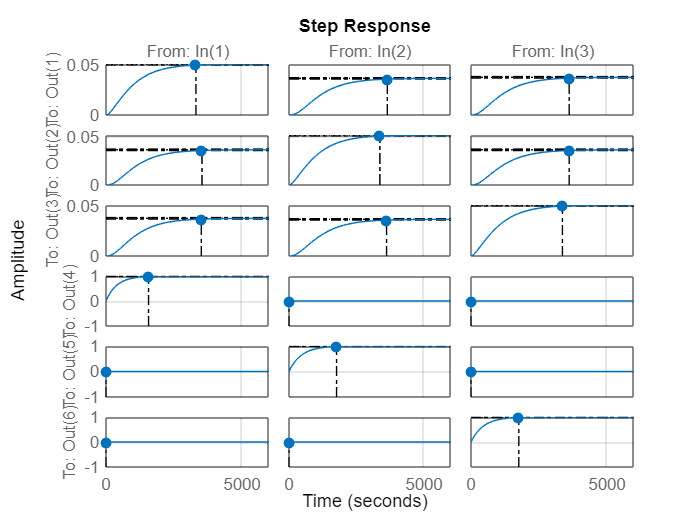

h = stepplot(continuous_time_ss);
grid on
h.showCharacteristic('TransientTime')

Dal grafico precedente si vede che il sistema arriva al valore di regime di temperatura dopo circa 3600 s, corrispondenti ad un'ora: per questo motivo si decide di scegliere un tempo di campionamento di 120 s, ovvero 2 minuti, di conseguenza le simulazioni del controllore devono essere superiori a 30 step.

Ts = 120; % [s], tempo di campionamento scelto. Per vincolo di uguaglianza impostare a 600
discrete_time_ss = c2d(continuous_time_ss,Ts,'tustin');
A = discrete_time_ss.A;
B = discrete_time_ss.B;
C = discrete_time_ss.C;

Per verificare la correttezza dell'operazione di discretizzazione, si possono analizzare gli autovalori della matrice A e il rango della matrice di raggiungibilità a tempo discreto.

lambda_i_dt = eig(A)

lambda_i_dt =     0.8482
    0.2067
    0.1090
    0.7391
    0.7647
    0.7647


Mr = ctrb(A,B);
rk_Mr = rank(Mr)

rk_Mr = 6

Mo = obsv(A,C);
rk_Mo = rank(Mo)

rk_Mo = 6

I risultati ottenuti a tempo discreto sono coerenti con quelli ottenuti a tempo continuo: gli autovalori hanno valore molto prossimo all'unità, ciò significa che sono lenti, inoltre il rango delle matrici di raggiungibilità e di osservabilità rimangono pari alla dimensione dello stato, che 6, perciò il sistema è completamente raggiungibile e completamente osservabile.

## Espressione dei vincoli nelle coordinate del sistema linearizzato

Il progetto del controllore MPC è legato al punto di equilibrio scelto, perché questo viene visto come se fosse l'origine del sistema. Per questo motivo, si devono riesprimere i vincoli e la condizione iniziale nelle coordinate del sistema linearizzato. 

x_ci_mpc = x_ci-x_eq;
x_eq_mpc = zeros(6,1); 
u_eq_mpc = zeros(3,1); 
x_max_mpc = x_max-x_eq;
x_min_mpc = x_min-x_eq;
u_max_mpc = u_max-u_eq;
u_min_mpc = u_min-u_eq;

## Calcolo del Control Invariant Set

Un ingredente necessario per progettare il controllore MPC è il Control Invariant Set (CIS). Le dimensioni di questo insieme dipendono dalla scelta delle matrici Q ed R del costo quadratico. Il CIS è calcolato iterativamente, ma prima bisogna esprimere i vincoli del sistema nella forma $H_x\;x \le hx, H_u\;u \le hu$.

**N.B.: **spuntare la casella "uguaglianza" se si è interessati al problema MPC con vincolo di uguaglianza (in questo caso i vincoli di massimo e minimo coincideranno con il punto di equilibrio), lasciarla inalterata altrimenti. Nel caso di vincolo di uguaglianza il CIS non verrà calcolato.

**N.B.:** se il punto di equilibrio non appartiene al CIS, l'esecuzione del codice viene interrotta.

uguaglianza = false; % Da spuntare se interessati a MPC con vincolo di uguaglianza
% Vincoli su stato e ingresso, espressi nella forma di <=
Hx = [eye(6); -eye(6)];
hx = [x_max_mpc;-x_min_mpc];
Hu = [eye(3); -eye(3)];
hu = [u_max_mpc;-u_min_mpc];
% Valori sulla diagonale delle matrici quadrate Q ed R
Q_val = 100;
R_val = 1;
Q = Q_val.*eye(6);
R = R_val.*eye(3);
% Chiamata alla funzione che calcola il CIS
if uguaglianza == true
    G = [eye(6); -eye(6)];
    g = zeros(12,1);
else
[G,g] = cis(A,B,x_eq_mpc,u_eq_mpc,Hx,hx,Hu,hu,Q,R);
end

ans = "iterato 1 volte"

CIS = Polyhedron(G,g);
% Stampa di alcune informazioni riguardanti il CIS appena calcolato
CIS.display()

Polyhedron in R^6 with representations:
    H-rep (redundant)   : Inequalities  12 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


CIS.isBounded()

ans = logical
   1


CIS.isEmptySet()

ans = logical
   0


CIS.isFullDim()

ans = logical
   1


CIS.isInside(x_eq_mpc)

ans = logical
   1


if ~(CIS.isInside(x_eq_mpc))
    error('Il punto di equilibrio non è contenuto nel Control Invariant Set!')
end

Dato che non è possibile visualizzare il grafico del poliedro, in quanto appartenente allo spazio 6D, si utilizzano delle funzioni di MPT3 per ricavare alcune proprietà di questo poliedro. Alcuni vincoli sono ridondanti, la regione individuata non è vuota ed è limitata, inoltre ha dimensione pari alla dimensione dello stato, che è 6. La condizione iniziale del problema non appartiene al CIS (questo è coerente, altrimenti avremmo poturo risolvere il problema del controllo con un semplice LQR).

## Visualizzazione del CIS

Un modo per poter visualizzare il CIS è quello di dividere la regione in base alle stanze, in questo modo si avranno tre grafici 2D che mostrano la regione ammissibile per ogni stanza.

% Stanza 1
G1 = G(:,[1,4]);
CIS1 = Polyhedron(G1,g)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  12 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


% Stanza 2
G2 = G(:,[2,5]);
CIS2 = Polyhedron(G2,g)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  12 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


% Stanza 3
G3 = G(:,[3,6]);
CIS3 = Polyhedron(G3,g)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  12 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


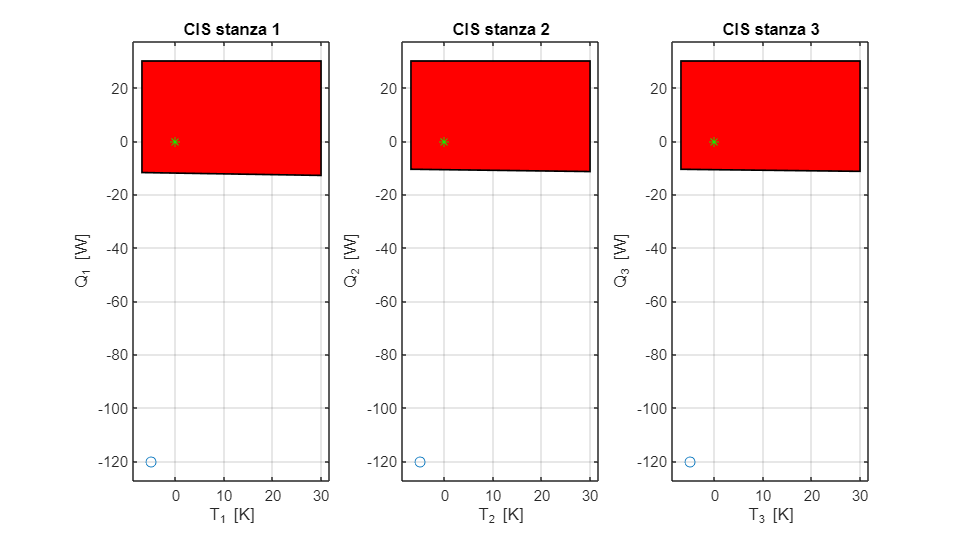

h = figure();
subplot(1,3,1)
plot(x_ci_mpc(1),x_ci_mpc(4),'o')
hold on
CIS1.plot()
plot(x_eq_mpc(1),x_eq_mpc(4),'*','Color','green')
title('CIS stanza 1');
xlabel('T_1 [K]');
ylabel('Q_1 [W]');
subplot(1,3,2)
plot(x_ci_mpc(2),x_ci_mpc(5),'o')
hold on
CIS2.plot()
plot(x_eq_mpc(2),x_eq_mpc(5),'*','Color','green')
title('CIS stanza 2');
xlabel('T_2 [K]');
ylabel('Q_2 [W]');
subplot(1,3,3)
plot(x_ci_mpc(3),x_ci_mpc(6),'o')
hold on
CIS3.plot()
plot(x_eq_mpc(3),x_eq_mpc(6),'*','Color','green')
title('CIS stanza 3');
xlabel('T_3 [K]');
ylabel('Q_3 [W]');
set(h,'Units','normalized','Position',[0 0 0.5 0.5]);

% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_CIS.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R1_CIS.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R10_CIS.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q1R1_CIS.png');

## Calcolo del N-step Controllable Set del Control Invariant Set

Una volta ottenuto il CIS, si calcola il set di punti tali che riescono ad entrare nel CIS in al più N step. Dato che siamo interessati al solo spazio degli stati, **x**, si proietterà in questo spazio anche l'N-step set, che appartiene invece allo spazio n+m.

**N.B.:** se il punto che rappresenta la condizione iniziale non appartiene all'N-step set, l'esecuzione del codice viene interrotta (per la proprietà di recursive feasibility: se la condizione iniziale del problema appartiene a N-step set, allora il controllore MPC risulta asintoticamente stabile; al contrario se la condizione iniziale non appartiene a questo set, non avremo questa garanzia).

% Orizzonte di predizione
if uguaglianza == true
    N = 3; 
else
    N = 5; 
end
[N_steps_H, N_steps_h] = controllable_set(Hx,hx,Hu,hu,G,g,A,B,N);
N_steps_set = Polyhedron('A', N_steps_H, 'b', N_steps_h);
N_steps_set.isBounded()

ans = logical
   1


N_steps_set.isEmptySet()

ans = logical
   0


N_steps_set.isFullDim()

ans = logical
   1


N_steps_set.isInside(x_ci_mpc)

ans = logical
   1


if ~(N_steps_set.isInside(x_ci_mpc))
    error('N-step set non contiene il punto iniziale, controllo non fattibile!')
end
% Stanza 1
N_steps_H1 = N_steps_H(:,[1,4]);
NsH1 = Polyhedron(N_steps_H1,N_steps_h)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities 215 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


% Stanza 2
N_steps_H2 = N_steps_H(:,[2,5]);
NsH2 = Polyhedron(N_steps_H2,N_steps_h)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities 215 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


% Stanza 3
N_steps_H3 = N_steps_H(:,[3,6]);
NsH3 = Polyhedron(N_steps_H3,N_steps_h)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities 215 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


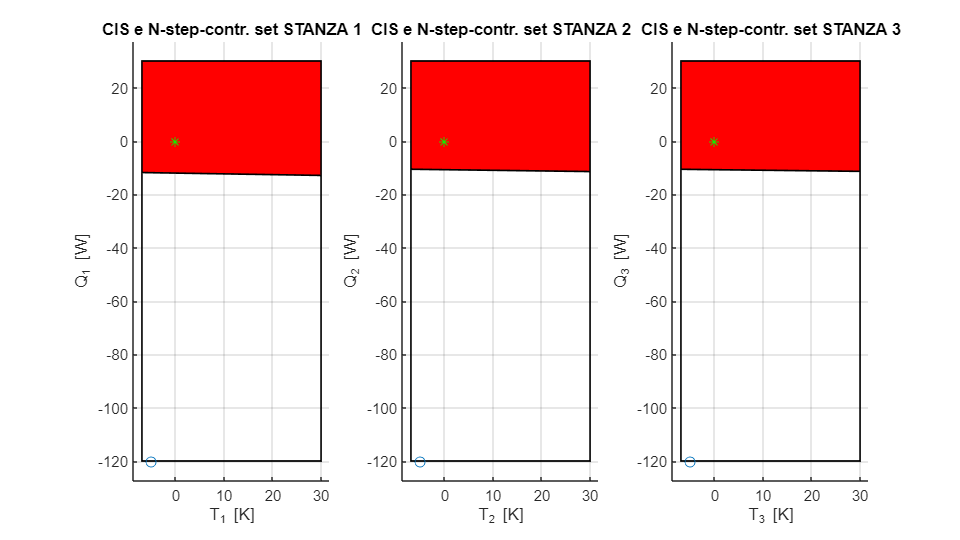

h = figure();
subplot(1,3,1)
NsH1.plot('Alpha',0)
hold on
plot(x_ci_mpc(1),x_ci_mpc(4),'o')
CIS1.plot()
plot(x_eq_mpc(1),x_eq_mpc(4),'*','Color','green')
title('CIS e N-step-contr. set STANZA 1');
xlabel('T_1 [K]');
ylabel('Q_1 [W]');
subplot(1,3,2)
NsH2.plot('Alpha',0)
hold on
plot(x_ci_mpc(2),x_ci_mpc(5),'o')
CIS2.plot()
plot(x_eq_mpc(2),x_eq_mpc(5),'*','Color','green')
title('CIS e N-step-contr. set STANZA 2');
xlabel('T_2 [K]');
ylabel('Q_2 [W]');
subplot(1,3,3)
NsH3.plot('Alpha',0)
hold on
plot(x_ci_mpc(3),x_ci_mpc(6),'o')
CIS3.plot()
plot(x_eq_mpc(3),x_eq_mpc(6),'*','Color','green')
title('CIS e N-step-contr. set STANZA 3');
xlabel('T_3 [K]');
ylabel('Q_3 [W]');
set(h,'Units','normalized','Position',[0 0 0.5 0.5]);

% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_Nstep.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R1_Nstep.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_Nstep_Ts5min.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q1R1_Nstep_Ts120.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_Nstep_Ts120.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q1R100_Nstep_Ts120.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q1R100_Nstep_Ts600.png');

## Design del controllore MPC e simulazione

Per progettare il controllore MPC è stata creata la funzione *mpc_ingredients*, che ha lo scopo di restituire in output i vettori e le matrici necessarie per poter utilizzare successivamente la funzione *quadprog*. Questi ingredienti sono stati parametrizzati rispetto ad N. Successivamente è stato iterato l'utilizzo della funzione *quadprog* lungo l'orizzonte di simulazione, in modo tale che la prima azione di controllo ottima restituita fosse applicata al sistema per poter ricavare poi lo stato all'istante successivo, da applicare come condizione iniziale per il problema di ottimizzazione all'iterazione successiva. La simulazione si interrompe nel caso in cui il problema diventa infattibile oppure se l'ottimizzatore restituisce delle soluzioni non corrette (in questo caso i flag conterrano valori tali per cui la somma logica è diversa da 1).

% Dimensioni matrici
nx = size(A,1);
nu = size(B,2);

%   Numero di step simulati
if uguaglianza == true
    T_sim = 10;
else
    T_sim = 60;
end

% Log stati e ingresso sistema
x_log = zeros(nx,T_sim+1);
u_log = zeros(nu,T_sim);
flags = zeros(1,T_sim);
x_log(:,1) = x_ci;

% Calcolo delle matrici necessarie per quadprog
[F,f_base,A_ineq,b_ineq_base,b_ineq_x0_factor] = mpc_ingredients(N,nx,nu,A,B,Q,R, ...
    Hx,hx,Hu,hu,G,g);

for tt = 1:T_sim
    %   Stato sistema linearizzato
    x_lin = x_log(:,tt)-x_eq;
    x_lin_shifted = x_lin - x_eq_mpc;

    %   Impostazioni MPC relative alla condizione iniziale
    f = f_base * x_lin;
    b_ineq = b_ineq_base - b_ineq_x0_factor * x_lin;
    
    %   Risoluzione problema di ottimizzazione
    options = optimset('Display', 'off');
    [delta_u_seq,~,exitflag] = quadprog(F,f,A_ineq,b_ineq,[],[],[],[],[],options);
    
    flags(tt) = exitflag;
    if flags(tt) == -2
        error('ERRORE: Il problema è infeasible!');
    end

    %   Risposta del sistema
    u_ottim = zeros(3,1);
    u_ottim(1) = delta_u_seq(1);
    u_ottim(2) = delta_u_seq(2);
    u_ottim(3) = delta_u_seq(3);
    u_log(:,tt) = u_eq + u_ottim;
    dxdt = @(t,x) uploadsystem(t,x,u_log(:,tt),k_bar,k_ext,T_ext,C_termica,tau);
    [~,xx] = ode45(dxdt,[0 Ts],x_log(:,tt));
    x_log(:,tt+1) = xx(end,:)';
end
% Controllo dei flag
if sum(flags ~= 1)
   error('Errore durante la risoluzione di quadprog!')
end

## Analisi delle prestazioni del controllore MPC progettato

Nei grafici seguenti si mostrano l'andamento degli ingressi e l'evoluzione del sistema con l'applicazione di questi ingressi. Le variabili di stato sono sempre raggruppate per stanza.

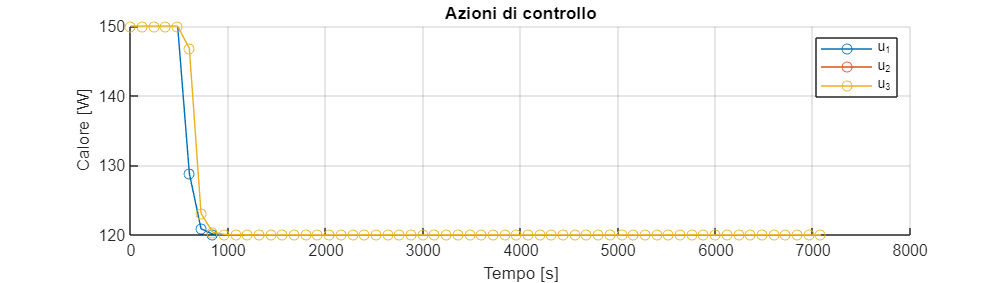

h = figure();
hold on
grid on
title('Azioni di controllo')
plot (1:Ts:T_sim*Ts,u_log(1,:),'-o')
plot (1:Ts:T_sim*Ts,u_log(2,:),'-o')
plot (1:Ts:T_sim*Ts,u_log(3,:),'-o')
xlabel('Tempo [s]');
ylabel('Calore [W]');
legend('u_1','u_2','u_3')
set(h,'Units','normalized','Position',[0 0 1 .5]); 

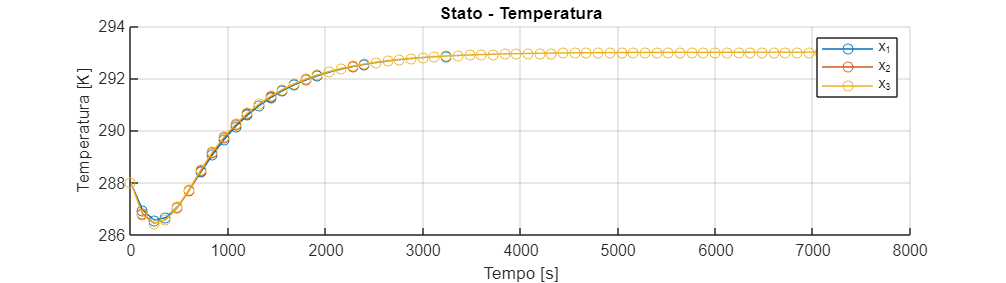

% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_u_log.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R1_u_log.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R10_u_log.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_u_log_Ts5min.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_u_log_Ts600s.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_u_log_Ts600s_cidx.png');

% Stanze - Temperatura
h = figure();
hold on
grid on
title('Stato - Temperatura')
plot (1:Ts:(T_sim+1)*Ts,x_log(1,:),'-o')
plot (1:Ts:(T_sim+1)*Ts,x_log(2,:),'-o')
plot (1:Ts:T_sim*(Ts+1),x_log(3,:),'-o')
xlabel('Tempo [s]');
ylabel('Temperatura [K]');
legend('x_1','x_2','x_3')
set(h,'Units','normalized','Position',[0 0 1 .5]); 

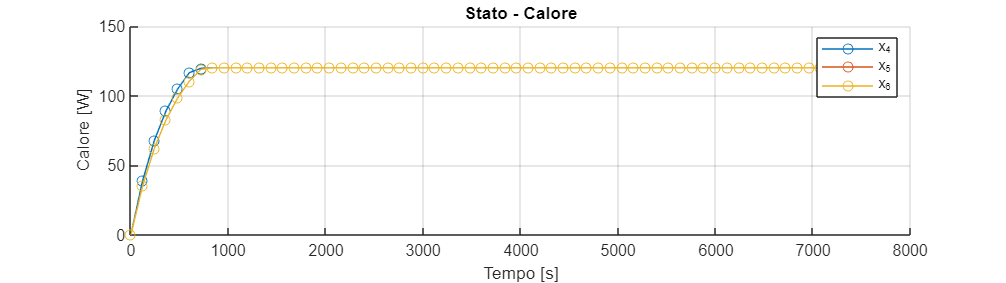

% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_x_log_t.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R1_x_log_t.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R10_x_log_t.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_x_log_t_Ts5min.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_x_log_t_Ts600s.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_x_log_t_Ts600s_cidx.png');

% Stanze - Calore
h = figure();
hold on
grid on
title('Stato - Calore')
plot (1:Ts:(T_sim+1)*Ts,x_log(4,:),'-o')
plot (1:Ts:(T_sim+1)*Ts,x_log(5,:),'-o')
plot (1:Ts:(T_sim+1)*Ts,x_log(6,:),'-o')
xlabel('Tempo [s]');
ylabel('Calore [W]');
legend('x_4','x_5','x_6')
set(h,'Units','normalized','Position',[0 0 1 .5]); 

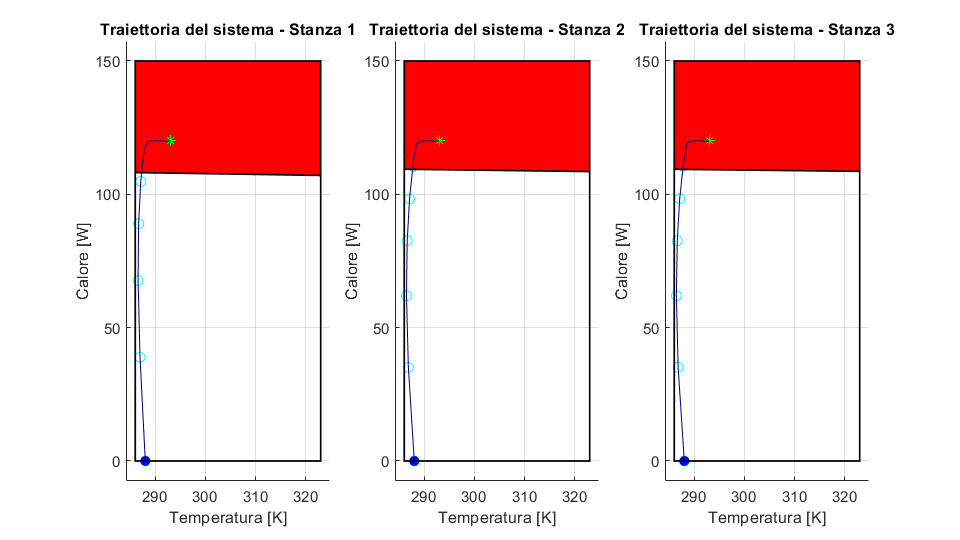

% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_x_log_q.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R1_x_log_q.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R10_x_log_q.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_x_log_q_Ts5min.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_x_log_q_Ts600s.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_x_log_q_Ts600s_cidx.png');

% Shift dei poliedri
CIS_shifted_1 = CIS1 + x_eq([1,4]);
Np_step_set_shifted_1 = NsH1 + x_eq([1,4]);
CIS_shifted_2 = CIS2 + x_eq([2,5]);
Np_step_set_shifted_2 = NsH2 + x_eq([2,5]);
CIS_shifted_3 = CIS3 + x_eq([3,6]);
Np_step_set_shifted_3 = NsH3 + x_eq([3,6]);

h = figure();
subplot(1,3,1)
hold on
scatter(x_log(1,:),x_log(4,:),'cyan');
scatter(x_log(1,1),x_log(4,1),'blue','Filled');
Np_step_set_shifted_1.plot('Alpha',0);
title('Traiettoria del sistema - Stanza 1');
xlabel('Temperatura [K]');
ylabel('Calore [W]');
CIS_shifted_1.plot()
plot(x_eq(1),x_eq(4),'*','Color','green')
plot(x_log(1,:),x_log(4,:),'Color',[0 0 0.5])

subplot(1,3,2)
hold on
scatter(x_log(2,:),x_log(5,:),'cyan');
scatter(x_log(1,1),x_log(4,1),'blue','Filled');
Np_step_set_shifted_2.plot('Alpha',0);
title('Traiettoria del sistema - Stanza 2');
xlabel('Temperatura [K]');
ylabel('Calore [W]');
CIS_shifted_2.plot()
plot(x_eq(2),x_eq(5),'*','Color','green')
plot(x_log(2,:),x_log(5,:),'Color',[0 0 0.5])

subplot(1,3,3)
hold on
scatter(x_log(3,:),x_log(6,:),'cyan');
scatter(x_log(1,1),x_log(4,1),'blue','Filled');
Np_step_set_shifted_3.plot('Alpha',0);
title('Traiettoria del sistema - Stanza 3');
xlabel('Temperatura [K]');
ylabel('Calore [W]');
CIS_shifted_3.plot()
plot(x_eq(3),x_eq(6),'*','Color','green')
plot(x_log(3,:),x_log(6,:),'Color',[0 0 0.5])
set(h,'Units','normalized','Position',[0 0 0.5 0.5]);

% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_traiettoria.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R1_traiettoria.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q1R10_traiettoria.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\DIS_Q100R1_traiettoria_Ts5min.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_traiettoria_Ts600s.png');
% saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S2\Controllo Avanzato\progetto\ProgettoCAM\controllo_temperatura_casa\simulazioni\DIS_Q100R1\U_Q100R1_traiettoria_Ts600s_cidx.png');

## Funzioni

Di seguito, si riporta la definizione delle funzioni utilizzate nelle sezioni precedenti.

1. Calcolo del Control Invariant Set

function [G,g] = cis(A,B,x_ref,u_ref,Fx,fx,Fu,fu,Q,R)
% Controllore LQR
K = -dlqr(A,B,Q,R); 
% Matrice A del sistema controllato con LQR
A_lqr = A+B*K;
% Vincoli su stato e ingresso
F = [Fx; Fu*K];
f = [fx; fu + Fu*(K*x_ref - u_ref)];
% Calcolo CIS (G*x<=g)
% Inizializzazione
CIS_poly_prev = Polyhedron(); % Poliedro vuoto
CIS_poly_curr = Polyhedron(F,f); % Poliedro fornito dai vincoli appena trovati
i=0; %%% DEBUG
while CIS_poly_prev.isEmptySet || CIS_poly_prev ~= CIS_poly_curr
    % Memorizzo il vecchio set candidato
    CIS_poly_prev = CIS_poly_curr;
    % Calcolo il nuovo set candidato (G_hat*x<=g_hat)
    G_hat = [CIS_poly_curr.A * A_lqr; F]; % tutti i vincoli stato
    g_hat = [CIS_poly_prev.b + CIS_poly_curr.A*B*(K*x_ref - u_ref); f];
    CIS_poly_curr = Polyhedron(G_hat,g_hat); % Poliedro con nuovi vincoli
    %%% DEBUG
    i=i+1;
    sprintf("iterazione %d",i);
    %{
    if i == 50
        break
    end
    %}
    %%%
end
sprintf("iterato %d volte",i)
G = CIS_poly_curr.A;
g = CIS_poly_curr.b;
end

2. Calcolo del N-step Controllable Set del Control Invariant Set

function [H_nsteps,h_nsteps] = controllable_set(Hx,hx,Hu,hu,H_target,h_target,A,B,N)
n = size(A,2);
m = size(B,2);

% Candidato iniziale
H_ii_steps = H_target;
h_ii_steps = h_target;

for li = 1:N
    % Computazione in R^(n+m)
    sprintf("iterazione %d", li); %%% DEBUG
    temp = Polyhedron('A', [H_ii_steps*A H_ii_steps*B; ...
        zeros(size(Hu,1),n) Hu], 'b', [h_ii_steps; hu]);

    % Proiezione in R^n
    temp = projection(temp, 1:n);
    temp.minHRep();

    % Intersezione con X := {x | Hx*x <= hx}
    H_ii_steps = [temp.A; Hx];
    h_ii_steps = [temp.b; hx];
end

H_nsteps = H_ii_steps;
h_nsteps = h_ii_steps;
end

3. Calcolo delle matrici richieste da quadrog

function [F,f_base,A_ineq,b_ineq_base,b_ineq_x0_factor] = mpc_ingredients(N,nx,nu,A,B, ...
    Q,R,Hx,hx,Hu,hu,G,g)
% Definizione della dinamica del sistema
A_italic = zeros(nx*(N+1),nx);
B_italic = zeros(nx*(N+1),nu*N);
B_italic_col = zeros(nx*N,nu);
for i = 0:1:N
    if(i==0)
        A_italic = eye(nx);
        B_italic_col(1:nx,:) = zeros(nx,nu);
    elseif(i==1)
        A_italic = [A_italic;A.^i];
        B_italic_col((i*nx)+1:(i+1)*nx,:) = B;
    else
        A_italic = [A_italic;A.^i];
        B_italic_col((i*nx)+1:(i+1)*nx,:) = (A.^(i-1))*B;
    end
end
for i = 0:1:N-1
    B_italic(:,(i*nu)+1:(i+1)*nu) = B_italic_col;
    B_italic_col = [zeros(nx,nu); B_italic_col(1:size(B_italic_col,1)-nx,:)];
end
% Trasformazione del costo
[K,P] = dlqr(A,B,Q,R);
Q_italic = zeros(nx*(N+1),nx*(N+1));
R_italic = zeros(nu*N,nu*N);
for i = 0:1:N-1
    Q_italic((i*nx)+1:(i*nx)+nx,(i*nx)+1:(i*nx)+nx) = diag(diag(Q));
    R_italic((i*nu)+1:(i*nu)+nu,(i*nu)+1:(i*nu)+nu) = diag(diag(R));
end

Q_italic((N*nx)+1:(N*nx)+nx,(N*nx)+1:(N*nx)+nx) = P;

prod = B_italic' * Q_italic * B_italic;

% Approssimazione di cifre non significative per incrementare la velocità
% di convergenza di quadprog (rendendo prod una matrice quadrata)
for i=1:length(prod)
    for j=1:length(prod)
            prod(i,j)=round(prod(i,j),5,"significant");
    end
end

F = R_italic + prod; 

f_base = (A_italic' * Q_italic * B_italic)';

% Calcolo matrici dei vincoli sugli ingressi
nHu = size(Hu,1);
nHx = size(Hx,1);
Hu_italic = zeros(nHu*N,nu*N);
hu_italic = zeros(nHu*N,1);
for i = 0:1:N-1
    if(i==0)
        hu_italic = hu;
        Hu_italic(1:nHu,:) = [Hu zeros(nHu,(N-1)*nu)];
    else
        hu_italic = [hu_italic;hu];
        if(i==N-1)
            Hu_italic((i*nHu)+1:(i*nHu)+nHu,:) = [zeros(nHu,i*nu) Hu];
        else
            Hu_italic((i*nHu)+1:(i*nHu)+nHu,:) = [zeros(nHu,i*nu) Hu zeros(nHu,(N-i-1)*nu)];
        end
    end
end

% Calcolo matrici dei vincoli sullo stato
Hx_italic = zeros(nHx*(N+1),(N+1)*nx);
hx_italic = zeros(nHx*(N+1),1);
for i = 0:1:N
    if(i==0)
        hx_italic = hx;
        Hx_italic(1:nHx,:) = [Hx zeros(nHx,N*nx)];
    else
        hx_italic = [hx_italic;hx];
        if(i==N)
            Hx_italic((i*nHx)+1:(i*nHx)+nHx,:) = [zeros(nHx,N*nx) Hx];
        else
            Hx_italic((i*nHx)+1:(i*nHx)+nHx,:) = [zeros(nHx,i*nx) Hx zeros(nHx,(N-i)*nx)];
        end
    end
end

G_italic = zeros(size(G,1),nx*(N+1));
G_italic(:,end-nx+1:end) = G;

Hx_italic = [Hx_italic; G_italic];

hx_italic = [hx_italic; g];

A_ineq = [Hu_italic; Hx_italic * B_italic];

b_ineq_base = [hu_italic; hx_italic];
b_ineq_x0_factor = [zeros(size(hu_italic,1),nx); Hx_italic * A_italic];

end

4. Aggiornamento del sistema con la prima azione di controllo ottenuta dal quadprog

function x_dot = uploadsystem(t,x,u,k_bar,k_ext,T_ext,C,tau)
x1_vect = [x(1);0;0];
x2_vect = [0;x(2);0];
x3_vect = [0;0;x(3)];
k12 = k_bar(1)+(4/(1+exp(-0.5*norm(x1_vect-x2_vect,2)))); 
k13 = k_bar(2)+(4/(1+exp(-0.5*norm(x1_vect-x3_vect,2)))); 
k23 = k_bar(3)+(4/(1+exp(-0.5*norm(x2_vect-x3_vect,2)))); 

% Equazioni di stato
x_dot = zeros(6,1);
x_dot(1) = (x(4) -k12*(x(1)-x(2)) -k13*(x(1)-x(3)) -k_ext*(x(1)-T_ext))/C(1);
x_dot(2) = (x(5) +k12*(x(1)-x(2)) -k23*(x(2)-x(3)) -k_ext*(x(2)-T_ext))/C(2);
x_dot(3) = (x(6) +k13*(x(1)-x(3)) +k23*(x(2)-x(3)) -k_ext*(x(3)-T_ext))/C(3);
x_dot(4) = (u(1)-x(4))/tau(1);
x_dot(5) = (u(2)-x(5))/tau(2);
x_dot(6) = (u(3)-x(6))/tau(3);

end